%% initialize environments
clc;
clear variables;

%% 算出時のパラメータの設定
mask_list = ["noMask", "withMask"];
vowels = ["a", "i", "u", "e", "o"];
Harvest_option.f0_floor = 175;  % F3
Harvest_option.f0_ceil = 265;   % C4
CheapTrick_option.fft_size = (2 ^ 8);
D4C_option.fft_size = CheapTrick_option.fft_size;

%% 長時間平均スペクトルの変数を初期化
vowels_long_term_average_spectrum = zeros(length(mask_list), ((CheapTrick_option.fft_size / 2) + 1));
consonants_long_term_average_spectrum = zeros(length(mask_list), ((CheapTrick_option.fft_size / 2) + 1));
vowels_counter = 0;
consonants_counter = 0;

%% 母音に関する長時間平均スペクトルを算出して表示する
for mask_index = 1 : length(mask_list)
    for file_index = 1 : 50
        %% load noMask audio file and confirm properties
        audio_file_path = "D:/名城大学/研究室/研究/Sources/AudioData/4モーラ単語リスト/Set 1/" + mask_list(mask_index) + "/set1_" + mask_list(mask_index) + "_word " + int2str(file_index) + ".wav";
        audio_file_manipulator = AudioFileManipulator(audio_file_path);
        audio_file_manipulator.load_properties();
        audio_file_manipulator.normalize();
        disp(audio_file_path);
    
        %% load noMask audio file label
        label_file_path = "D:/名城大学/研究室/研究/Sources/AudioData/4モーラ単語リスト/Set 1/" + mask_list(mask_index) + "_label/set1_" + mask_list(mask_index) + "_word " + int2str(file_index) + "_label.txt";
        label = sploadlabel(label_file_path, "sec");

        %% calculate basic frequencies, power spectrogram, aperiodicity parameters and save to mat file
        source_information = Harvest(audio_file_manipulator.signal, audio_file_manipulator.sample_rate, Harvest_option);
        spectrum_parameters = CheapTrick(audio_file_manipulator.signal, audio_file_manipulator.sample_rate, source_information, CheapTrick_option);
        aperiodicity_structure = D4C(audio_file_manipulator.signal, audio_file_manipulator.sample_rate, source_information, D4C_option);
        
        %% calculate long term average spectrum
        column_size = size(spectrum_parameters.spectrogram, 2);
        gain = length(aperiodicity_structure.temporal_positions) / aperiodicity_structure.temporal_positions(end);

        for phoneme_index = 1 : (length(label) - 1)
            start_frame = int64(label(phoneme_index).time * gain);
            end_frame = int64(label(phoneme_index + 1).time * gain);
            long_term_average_spectrum = sum(spectrum_parameters.spectrogram(:, start_frame : end_frame), 2) ./ column_size;
            if sum(strcmp(label(phoneme_index).phoneme, vowels)) == 1
                vowels_long_term_average_spectrum(mask_index, :) = vowels_long_term_average_spectrum(mask_index, :) + long_term_average_spectrum';
                vowels_counter = vowels_counter + 1;
            else
                consonants_long_term_average_spectrum(mask_index, :) = consonants_long_term_average_spectrum(mask_index, :) + long_term_average_spectrum';
                consonants_counter = consonants_counter + 1;
            end
        end
    end
end

D:/名城大学/研究室/研究/Sources/AudioData/4モーラ単語リスト/Set 1/noMask/set1_noMask_word 1.wav
D:/名城大学/研究室/研究/Sources/AudioData/4モーラ単語リスト/Set 1/noMask/set1_noMask_word 2.wav
D:/名城大学/研究室/研究/Sources/AudioData/4モーラ単語リスト/Set 1/noMask/set1_noMask_word 3.wav
D:/名城大学/研究室/研究/Sources/AudioData/4モーラ単語リスト/Set 1/noMask/set1_noMask_word 4.wav
D:/名城大学/研究室/研究/Sources/AudioData/4モーラ単語リスト/Set 1/noMask/set1_noMask_word 5.wav
D:/名城大学/研究室/研究/Sources/AudioData/4モーラ単語リスト/Set 1/noMask/set1_noMask_word 6.wav
D:/名城大学/研究室/研究/Sources/AudioData/4モーラ単語リスト/Set 1/noMask/set1_noMask_word 7.wav
D:/名城大学/研究室/研究/Sources/AudioData/4モーラ単語リスト/Set 1/noMask/set1_noMask_word 8.wav
D:/名城大学/研究室/研究/Sources/AudioData/4モーラ単語リスト/Set 1/noMask/set1_noMask_word 9.wav
D:/名城大学/研究室/研究/Sources/AudioData/4モーラ単語リスト/Set 1/noMask/set1_noMask_word 10.wav
D:/名城大学/研究室/研究/Sources/AudioData/4モーラ単語リスト/Set 1/noMask/set1_noMask_word 11.wav
D:/名城大学/研究室/研究/Sources/AudioData/4モーラ単語リスト/Set 1/noMask/set1_noMask_word 12.wav
D:/名城大学/研究室/研究/Sources/AudioData/4モーラ単語リスト/Set 1/

%% 母音に関する長時間平均スペクトルを算出する際のパラメータを設定
frequency_axis = (1 : length(vowels_long_term_average_spectrum)) ./ length(vowels_long_term_average_spectrum) .* (audio_file_manipulator.sample_rate / 2);
frequency_limit_range = [1, (audio_file_manipulator.sample_rate / 4)];
frequency_label = "Frequency [Hz]";
magnitude_label = "Magnitude [dB]";
title_label = "Comparison of long-term average spectrum";
font_size = 30;
plot_format = ["b-", "r--"];

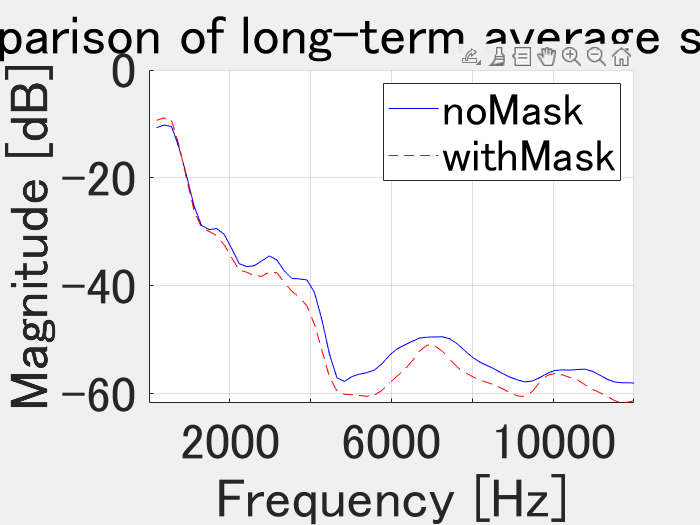

%% 母音に関する長時間平均スペクトルを描画
set(gcf, "visible", "on");
figure.WindowState = "maximized";
hold on;
grid on;
xlabel(frequency_label);
ylabel(magnitude_label);
title(title_label);
xlim(frequency_limit_range);
set(gca, "FontSize", font_size)
for mask_index = 1 : length(mask_list)
    plot(frequency_axis, 10 * log10(vowels_long_term_average_spectrum(mask_index, :) ./ vowels_counter), plot_format(mask_index));
end
legend(mask_list);
png_path = "D:/名城大学/研究室/研究/Outputs/4モーラ単語リスト/Set1/both/LongTermAverageSpectrum/phoneme/vowels.png";
emf_path = "D:/名城大学/研究室/研究/Outputs/4モーラ単語リスト/Set1/both/LongTermAverageSpectrum/phoneme/vowels.emf";
saveas(gcf, png_path);
saveas(gcf, emf_path);

clf(gcf);
delete(gcf);